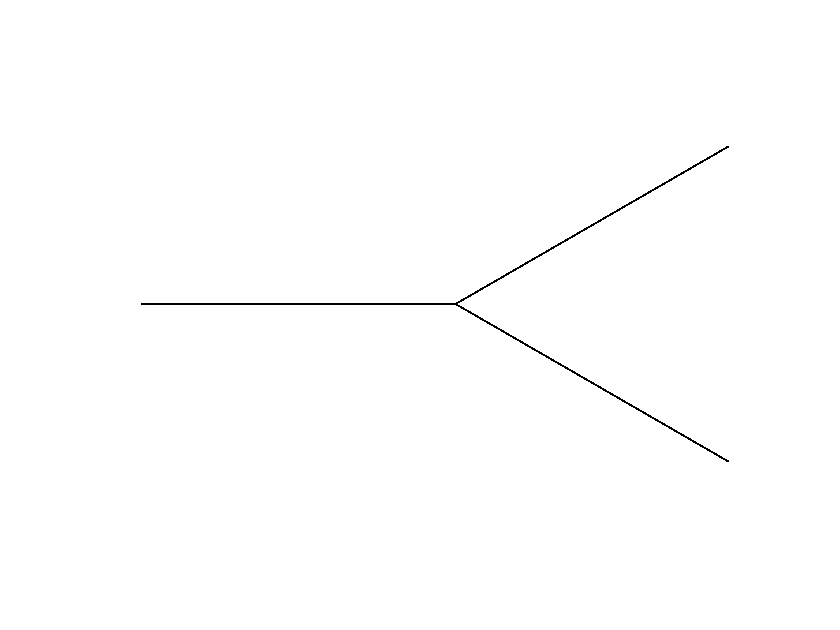

Current plot held


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


clear
X = [0; 10;  18.6603; 18.6603];
Y = [0; 0; 5; -5];
dA = [0 0 0 0;1 0 0 0; 0 1 0 0; 0 1 0 0];
d = dendrite(dA,X,Y,[]);
d.plot


C = [0; 100; 50; 50]*10^-12;
T = cell(4,1);
s = tf('s');

for i = 2:length(X)
    T{i} = s*ones(2);
    T{i}(1,1) = tf([d.R(i)*C(i) 1],1);
    T{i}(1,2) = tf([d.R(i)],1);
    T{i}(2,1) = tf([C(i) 0],1);
    T{i}(2,2) = tf(1,1);
end

T34eq = Y2ABCD(ABCD2Y(T{3}) + ABCD2Y(T{4}));
T234eq  = T{2}*T34eq;

Zosc = minreal(T234eq(1,2)/T234eq(1,1))


Zosc =
 
     1e10 s + 2e18
  -------------------
  s^2 + 3e08 s + 1e16
 
Continuous-time transfer function.



%bode(Zosc)
bandwidth(Zosc)/(2*pi)      

ans = 6.1567e+06

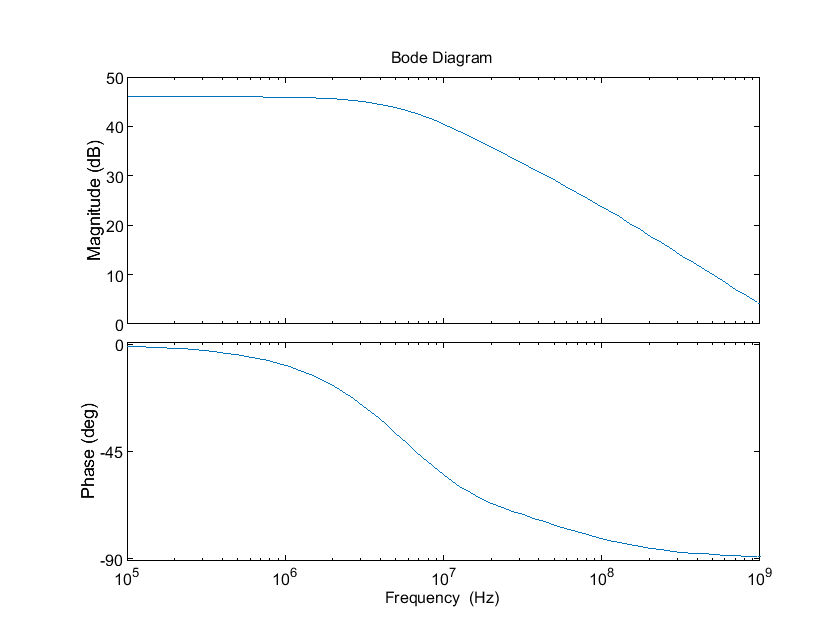


opts = bodeoptions;
opts.FreqUnits = 'Hz';
bodeplot(Zosc, opts)

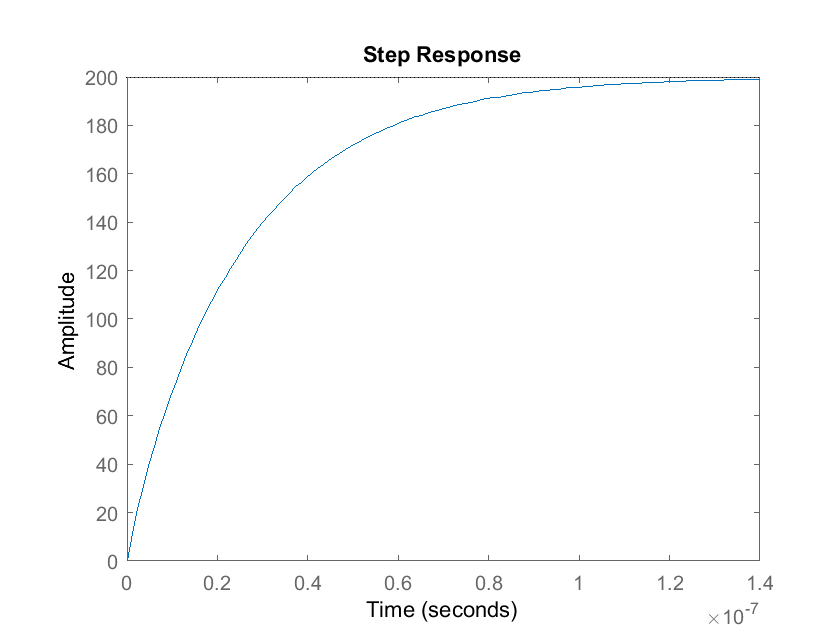

step(Zosc)